# ASEN 3128: Homework 1

### William Watkins

In collaboration with Ponder Stine

## Prepare workspace

close all;
clear all;
clc;

## Declare Constants

global mass C_d p A W_N W_E W_D

mass = 0.03; % [kg]
dia = 0.03; % [m], diameter of golf ball
C_d = 0.6; % Coefficient of drag of golfball
x_i = 0.0; % [m], initial x-position of the ball
y_i = 0.0; % [m], initial y-position of the ball
z_i = 0.0; % [m], initial z-position of the ball
V_Ni = 0.0; % [m/s], initial velocity in N direction
V_Ei = 20.0; % [m/s], initial velocity in E direction
V_Di = -20.0; % [m/s], initial velocity in D direction
W_N = 0.0; % [m/s], wind initial velocity in N direction
W_E = 0.0; % [m/s], wind initial velocity in N direction
W_D = 0.0; % [m/s], wind initial velocity in N direction
p = 1.225; % [kg/m^3], density of air
A = 3.1415926 * (dia/2) ^2; % [m^2], cross sectional area of the ball

## Part A

### Preparing for ODE45

Initials = [x_i y_i z_i V_Ni V_Ei V_Di]; % Declaring the initial state vector for ODE45

tSpan = 0:0.001:10; % [s], time range for ODE45 plotting

options = odeset('Events', @golfballEventsFcn);

### Call the ODE

[tA, yA, teA, yeA, ieA] = ode45(@golfballFlight, tSpan, Initials, options);
maxDistance = max(yA(:,2))

maxDistance = 54.1501

The distance the golfball flies is 54.2 meters.  From checking with other students, this answer seems to be valid.  Additionally, the time of flight of the golfball is approximately 3 seconds.  Incorporating aerodynamics drag and an initial horizontal velocity of 20 m/s, 54.2 meters makes logical sense.

## Part B

### Constants

W_N = 1.0;

### Preparing for ODE45

Initials = [x_i y_i z_i V_Ni V_Ei V_Di]; % Declaring the initial state vector for ODE45

tSpan = 0:0.001:10; % [s], time range for ODE45 plotting

options = odeset('Events', @golfballEventsFcn);

### Call the ODE

[tB, yB, teB, yeB, ieB] = ode45(@golfballFlight, tSpan, Initials, options);
W_N = 2.0;
[tB2, yB2, teB, yeB, ieB] = ode45(@golfballFlight, tSpan, Initials, options);
windDeflection = max(yB(:,1))

windDeflection = 2.7068

windDeflection = max(yB2(:,1))

windDeflection = 5.4090

For the initial conditions given for the velocity of the golfball, the landing location varies by 2.71 meters for every 1 meter per second of North wind speed.

## Part C

### Increasing the Mass

#### Declaring Constants

W_N = 0.0;
KE_i = 0.5 * mass * norm([V_Ni V_Ei V_Di]);
mass = 0.05;
V_mag = KE_i * 2 / mass;
V_Ei = V_mag * cosd(45);
V_Di = -V_mag * cosd(45);

#### Preparing for ODE45

Initials = [x_i y_i z_i V_Ni V_Ei V_Di]; % Declaring the initial state vector for ODE45

tSpan = 0:0.001:10; % [s], time range for ODE45 plotting

options = odeset('Events', @golfballEventsFcn);

#### Call the ODE

[tC1, yC1, teC1, yeC1, ieC1] = ode45(@golfballFlight, tSpan, Initials, options);

### Decreasing the Mass

#### Declaring Constants

KE_i = 0.5 * mass * norm([V_Ni V_Ei V_Di]);
mass = 0.01;
V_mag = KE_i * 2 / mass;
V_Ei = V_mag * cosd(45);
V_Di = -V_mag * cosd(45);

#### Preparing for ODE45

Initials = [x_i y_i z_i V_Ni V_Ei V_Di]; % Declaring the initial state vector for ODE45

tSpan = 0:0.001:10; % [s], time range for ODE45 plotting

options = odeset('Events', @golfballEventsFcn);

#### Call the ODE

[tC2, yC2, teC2, yeC2, ieC2] = ode45(@golfballFlight, tSpan, Initials, options);

## Analysing the Data

maxDIncrease = max(yC1(:,2))

maxDIncrease = 26.2888

maxDDecrease = max(yC2(:,2))

maxDDecrease = 72.4692

The distance flown by the golfball will increase if the mass is decreased while the kinetic energy is kept constant.

## Plotting Flights

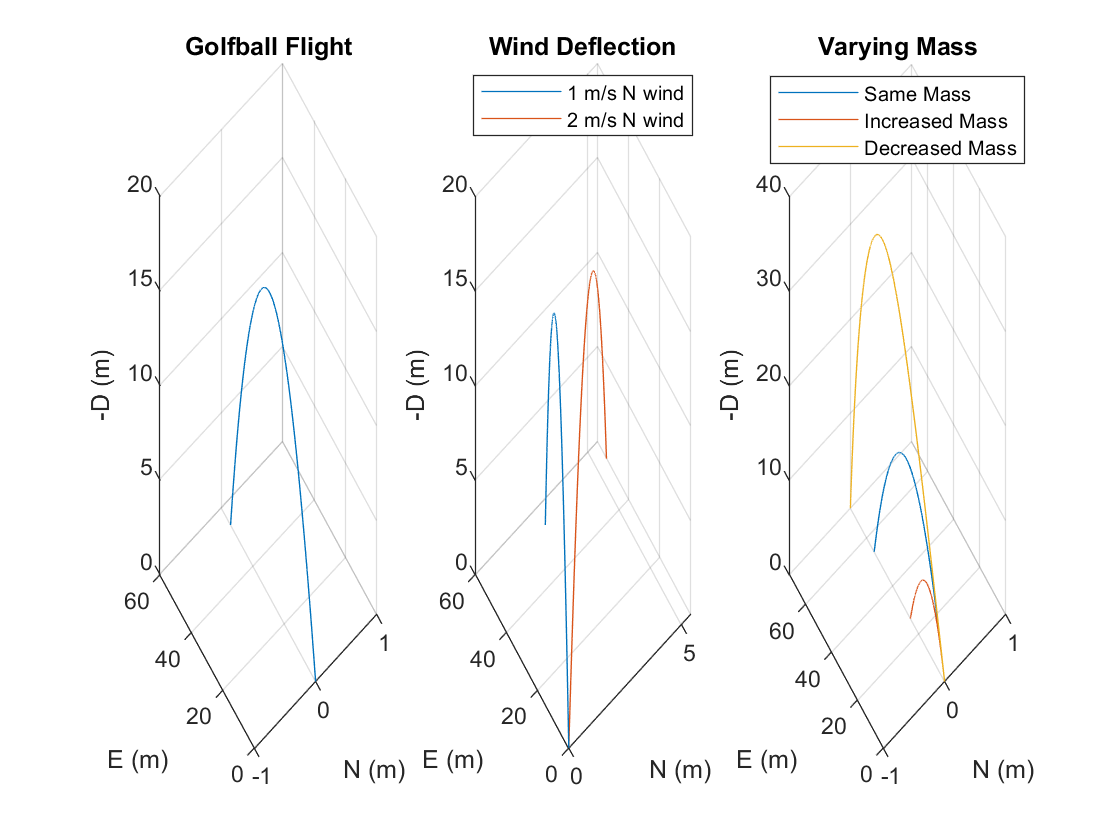

figure('Name', 'Golfball Flights');

subplot(1,3,1);
plot3(yA(:,1), yA(:,2), -yA(:,3));
title('Golfball Flight');
xlabel('N (m)');
ylabel('E (m)');
zlabel('-D (m)');
grid on

subplot(1,3,2);
plot3(yB(:,1), yB(:,2), -yB(:,3));
title('Wind Deflection')
xlabel('N (m)');
ylabel('E (m)');
zlabel('-D (m)');
grid on
hold on
plot3(yB2(:,1), yB2(:,2), -yB2(:,3));
legend({'1 m/s N wind','2 m/s N wind'},'Location','best')
hold off

subplot(1,3,3);
plot3(yA(:,1), yA(:,2), -yA(:,3));
hold on
plot3(yC1(:,1), yC1(:,2), -yC1(:,3));
hold on
plot3(yC2(:,1), yC2(:,2), -yC2(:,3));
legend({'Same Mass','Increased Mass','Decreased Mass'},'Location','best')
title('Varying Mass')
xlabel('N (m)');
ylabel('E (m)');
zlabel('-D (m)');
grid on

### Functions

function [EquationsOfMotion] = golfballFlight(t, State)
%golfballFlight contains the equations that ODE45 uses to model the flight
%of the golfball

%% Define global variables

global mass C_d p A W_N W_E W_D

%% Gather State variables

N = State(1); % [m], initial x-position of the ball
E = State(2); % [m], initial y-position of the ball
D = State(3); % [m], initial z-position of the ball
V_N = State(4) + W_N; % [m/s], initial velocity in N direction
V_E = State(5) + W_E; % [m/s], initial velocity in E direction
V_D = State(6) + W_D; % [m/s], initial velocity in D direction

%% Non-differential equations

Vmag = sqrt(V_N^2 + V_E^2 + V_D^2); % [m/s], magnitude of the velocity

Drag = (p / 2) * (Vmag ^ 2) * C_d * A; % [N], drag on the golfball as it flies

%% Heading Components

hN = V_N / Vmag; % North heading
hE = V_E / Vmag; % East heading
hD = V_D / Vmag; % Down heading

%% Differential Equations

% Velocity Equations
dNdt = V_N;
dEdt = V_E;
dDdt = V_D;

% Acceleration equations
dVNdt = -Drag * (hN / mass);
dVEdt = -Drag * (hE / mass);
dVDdt = -Drag * (hD / mass) + 9.81;

%% Create change vector

EquationsOfMotion(1) = dNdt;
EquationsOfMotion(2) = dEdt;
EquationsOfMotion(3) = dDdt;
EquationsOfMotion(4) = dVNdt;
EquationsOfMotion(5) = dVEdt;
EquationsOfMotion(6) = dVDdt;
EquationsOfMotion = EquationsOfMotion';

end

function [value, isterminal, direction] = golfballEventsFcn(~,y)
%golfballEventsFcn stops the ODE45 integrator when the golfball hits the
%ground

value = y(3); % Looking for the z-position to be 0;
isterminal = 1; % Make sure ODE45 stops when we hit this event
direction = 1; % Only marks zeros after z has started to decrease again

end